# **TP2**

## Ejercicio 1

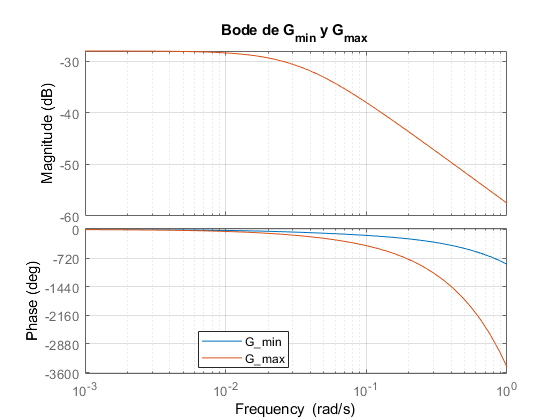

s = tf('s');

Lmax = 58.742;
Lmin = 13.707;

G = (0.04)/(30*s + 1);
Gmax = G;
Gmin = G;
Gmax.IODelay = Lmax;
Gmin.IODelay = Lmin;

% --- Bode Plot de ambas ---
figure;
bode(Gmin,Gmax);
grid on;
legend('G_{min}','G_{max}','Location','best');
title('Bode de G_{min} y G_{max}');


% --- Márgenes de ganancia y fase ---
[GMmin, PMmin, Wcg_min, Wcp_min] = margin(Gmin);
[GMmax, PMmax, Wcg_max, Wcp_max] = margin(Gmax);

fprintf('Gmin -> Margen de ganancia: %.2f dB, Margen de fase: %.2f°, Wcg: %.2f rad/s, Wcp: %.2f rad/s\n',...
        20*log10(GMmin), PMmin, Wcg_min, Wcp_min);

Gmin -> Margen de ganancia: 40.22 dB, Margen de fase: Inf°, Wcg: 0.13 rad/s, Wcp: NaN rad/s



fprintf('Gmax -> Margen de ganancia: %.2f dB, Margen de fase: %.2f°, Wcg: %.2f rad/s, Wcp: %.2f rad/s\n',...
        20*log10(GMmax), PMmax, Wcg_max, Wcp_max);

Gmax -> Margen de ganancia: 31.68 dB, Margen de fase: Inf°, Wcg: 0.04 rad/s, Wcp: NaN rad/s


## Ejercicio 2

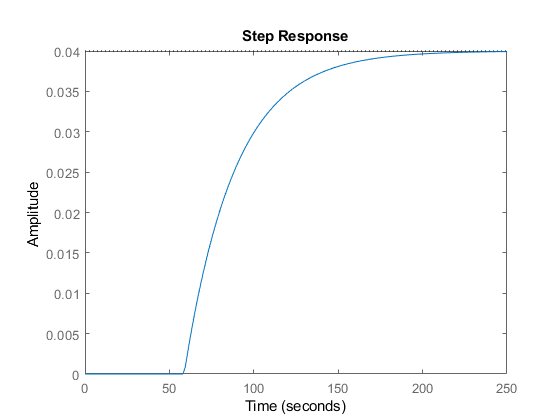

s = tf('s');

Lmax = 58.742;
Lmin = 13.707;

G = (0.04)/(30*s + 1);
Gmax = G;
Gmin = G;
Gmax.IODelay = Lmax;
Gmin.IODelay = Lmin;

step(Gmax);

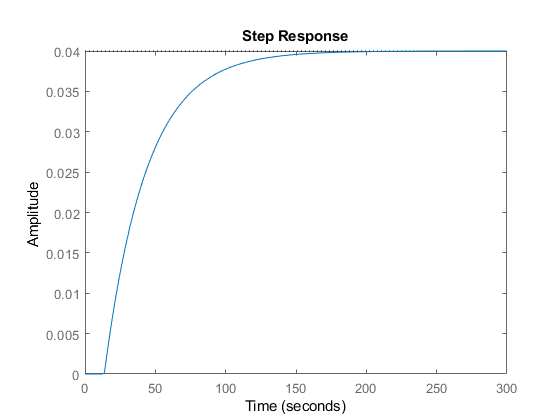

step(Gmin);

## Ejercicio 3